## Examen Final de Modelado (PRACTICA)

### Ejercicio #1

Primero obtenemos los datos de las funciones para encontrar los parámetros de nuestras funciones S(t) y U(t)

Insertamos los valores de las funciones evaluadas en dos puntos y esos dos puntos. El programa realiza el despeje para las constantes de las funciones. 


% datoCmin = 5000;
% datosCmax  = 5500;
% tcmin =0.5;
% tcmax =1;
% divt1 = tcmax-tcmin;
% datosCdiv = datosCmax/datoCmin;
% b = log(datosCdiv)/divt1
% a = datosCmax/exp(b*tcmax)
b = 0.75

b = 0.7500

a = 12000

a = 12000


%Ojo ya que la exponencial de S(t) tiene argumento negativo el datos con nombre max siempre será menor
% datosSmin = 3500000;
% datosSmax = 3200000;
% tsmin = 0;
% tsmax = 1;
% divt2 = tsmax-tsmin;
% datosSdiv = datosSmax/datosSmin;
d = 0.7

d = 0.7000

c = 4000000

c = 4000000

Creamos las funciones con las constantes anteriormente obtenidas. 

syms t
funS = @(t) c*exp(-d*t);
funC = @(t) a*exp(b*t);

K = funS(0)

K = 4000000

Linea auxiliar debido a que la función G de costos incluye una integral, por ello debemos obtener el resultado simbólico de la integral y convertirlo a función del tiempo

funCintegrada = matlabFunction(int(funC,0,t))

funCintegrada = function_handle with value:
    @(t)exp(t.*(3.0./4.0)).*1.6e+4-1.6e+4


Creamos la función G(t) y la graficamos en un intervalo limitado

G = @(t) K/t + 1/t*funCintegrada(t) -funS(t)/t

G = function_handle with value:
    @(t)K/t+1/t*funCintegrada(t)-funS(t)/t


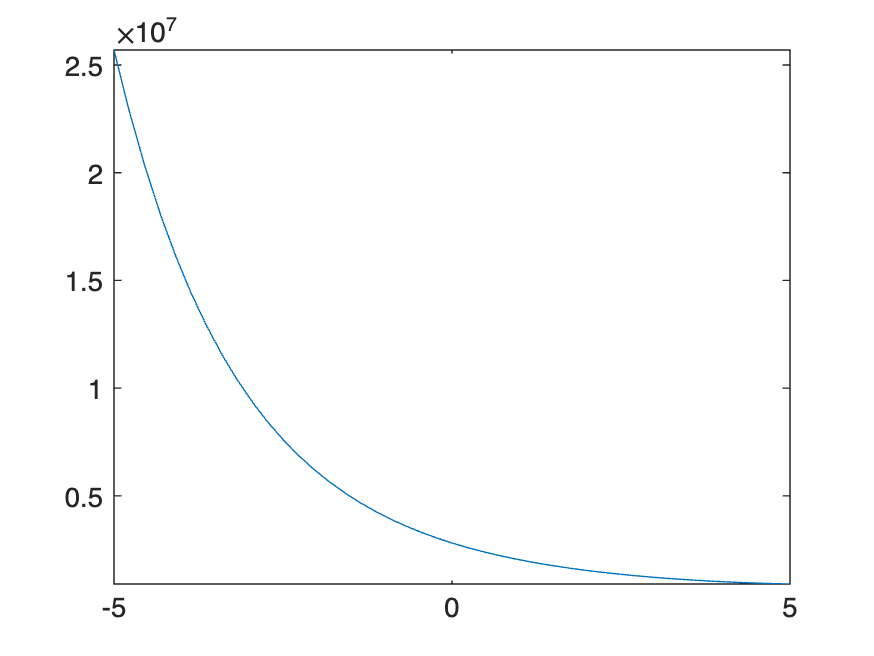

fplot(G)

Observamos que el mínimo sucede alrrededor del cinco, debemos dar esto como parámetros a nuestro método Newton Rhapson junto con la función G para encontrar el mínimo. 

La función genera el tiempo óptimo así como el valor de la función objetivo en ese punto. 

[tOpt, fObj] = newtonRaphsonMinimo(G, 5)

tOpt = 5.6554

fObj = 8.8763e+05

### Ejercicio #1 pt. 2

% datoCmin = 5000;
% datosCmax  = 5500;
% tcmin =0.5;
% tcmax =1;
% divt1 = tcmax-tcmin;
% datosCdiv = datosCmax/datoCmin;
% b = log(datosCdiv)/divt1
% a = datosCmax/exp(b*tcmax)
b = 0.26

b = 0.2600

a = 1000

a = 1000


%Ojo ya que la exponencial de S(t) tiene argumento negativo el datos con nombre max siempre será menor
datosSmin = 3500000;
datosSmax = 3200000;
tsmin = 0;
tsmax = 1;
divt2 = tsmax-tsmin;
datosSdiv = datosSmax/datosSmin;
d = -log(datosSdiv)/divt2

d = 0.0896

c = datosSmax/exp(-d*tsmax)

c = 3500000

Creamos las funciones con las constantes anteriormente obtenidas. 

syms t
funS = @(t) c*exp(-d*t);
funC = @(t) a*exp(b*t);

g = 3500000

g = 3500000

h = 0.041964

h = 0.0420

funK = @(t) g*exp(h*t);

Linea auxiliar debido a que la función G de costos incluye una integral, por ello debemos obtener el resultado simbólico de la integral y convertirlo a función del tiempo

funCintegrada = matlabFunction(int(funC,0,t))

funCintegrada = function_handle with value:
    @(t)exp(t.*(1.3e+1./5.0e+1)).*3.846153846153846e+3-3.846153846153846e+3


Creamos la función G(t) y la graficamos en un intervalo limitado

G = @(t) funK(t)/t + 1/t*funCintegrada(t) -funS(t)/t

G = function_handle with value:
    @(t)funK(t)/t+1/t*funCintegrada(t)-funS(t)/t


fplot(G, [0,30])

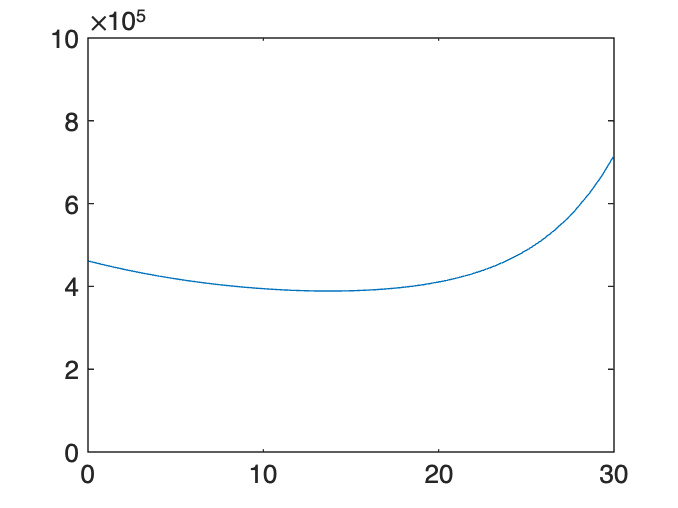

axis([0 30 0 1e6])

Observamos que el mínimo sucede alrrededor del cinco, debemos dar esto como parámetros a nuestro método Newton Rhapson junto con la función G para encontrar el mínimo. 

La función genera el tiempo óptimo así como el valor de la función objetivo en ese punto. 

[tOpt, fObj] = newtonRaphsonMinimo(G, 16)

tOpt = 13.7519

fObj = 3.8873e+05

### Pregunta #2

Calculos de G y t para la función 1. También se despliega la gráfica cambiando las alhpas.  

alpha = 0.1

alpha = 0.1000

G1 = @(t)  (t+alpha*(1-t))./(t-t.^2/2);
fplot(G1)
hold on
[tOpt, fObj] = newtonRaphsonMinimo(G1, 1)

tOpt = 0.3732

fObj = 1.4359

alpha = 0.2

alpha = 0.2000

G1 = @(t)  (t+alpha*(1-t))./(t-t.^2/2);
fplot(G1)
[tOpt, fObj] = newtonRaphsonMinimo(G1, 1)

tOpt = 0.5000

fObj = 1.6000

alpha = 0.3

alpha = 0.3000

G1 = @(t)  (t+alpha*(1-t))./(t-t.^2/2);
fplot(G1)
[tOpt, fObj] = newtonRaphsonMinimo(G1, 1)

tOpt = 0.5916

fObj = 1.7141

alpha = 0.4

alpha = 0.4000

G1 = @(t)  (t+alpha*(1-t))./(t-t.^2/2);
fplot(G1)
[tOpt, fObj] = newtonRaphsonMinimo(G1, 1)

tOpt = 0.6667

fObj = 1.8000

alpha = 0.5

alpha = 0.5000

G1 = @(t)  (t+alpha*(1-t))./(t-t.^2/2);
fplot(G1)
[tOpt, fObj] = newtonRaphsonMinimo(G1, 1)

tOpt = 0.7321

fObj = 1.8660

alpha = 0.6

alpha = 0.6000

G1 = @(t)  (t+alpha*(1-t))./(t-t.^2/2);
fplot(G1)
[tOpt, fObj] = newtonRaphsonMinimo(G1, 1)

tOpt = 0.7913

fObj = 1.9165

alpha = 0.7

alpha = 0.7000

G1 = @(t)  (t+alpha*(1-t))./(t-t.^2/2);
fplot(G1)
[tOpt, fObj] = newtonRaphsonMinimo(G1, 1)

tOpt = 0.8465

fObj = 1.9539

alpha = 0.8

alpha = 0.8000

G1 = @(t)  (t+alpha*(1-t))./(t-t.^2/2);
fplot(G1)
[tOpt, fObj] = newtonRaphsonMinimo(G1, 1)

tOpt = 0.8990

fObj = 1.9798

alpha = 0.9

alpha = 0.9000

G1 = @(t)  (t+alpha*(1-t))./(t-t.^2/2);
fplot(G1)
%axis([0.01 2 0 10])

[tOpt, fObj] = newtonRaphsonMinimo(G1, 1)

tOpt = 0.9499

fObj = 1.9950

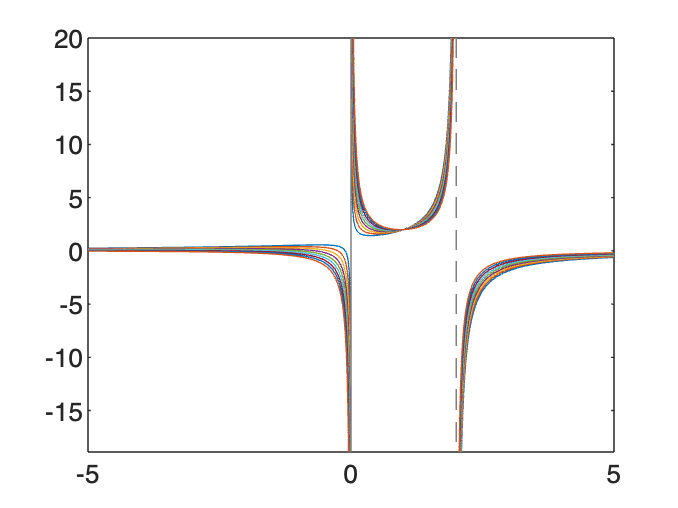

%legend()
hold off

### Pregunta #2

Calculos de G y t para la función 2 También se despliega la gráfica.

fun = @(t) 3*(2*t-t.^2+alpha*(1-2*t+t.^2))./(t*(t.^2-3*t+3));
alpha = 0.1

alpha = 0.1000

G1 = @(t) 3*(2*t-t.^2+alpha*(1-2*t+t.^2))./(t*(t.^2-3*t+3));
fplot(G1)

hold on
[tOpt, fObj] = newtonRaphsonMinimo(G1, 0.3)

tOpt = 0.2948

fObj = 2.5524

alpha = 0.2

alpha = 0.2000

G1 = @(t) 3*(2*t-t.^2+alpha*(1-2*t+t.^2))./(t*(t.^2-3*t+3));
fplot(G1)

[tOpt, fObj] = newtonRaphsonMinimo(G1, 0.3)

tOpt = 0.4126

fObj = 2.7240

alpha = 0.3

alpha = 0.3000

G1 = @(t) 3*(2*t-t.^2+alpha*(1-2*t+t.^2))./(t*(t.^2-3*t+3));
fplot(G1)

[tOpt, fObj] = newtonRaphsonMinimo(G1, 0.3)

tOpt = 0.5050

fObj = 2.8285

alpha = 0.4

alpha = 0.4000

G1 = @(t) 3*(2*t-t.^2+alpha*(1-2*t+t.^2))./(t*(t.^2-3*t+3));
fplot(G1)

[tOpt, fObj] = newtonRaphsonMinimo(G1, 0.3)

tOpt = 0.5858

fObj = 2.8971

alpha = 0.5

alpha = 0.5000

G1 = @(t) 3*(2*t-t.^2+alpha*(1-2*t+t.^2))./(t*(t.^2-3*t+3));
fplot(G1)

[tOpt, fObj] = newtonRaphsonMinimo(G1, 0.3)

tOpt = 0.6601

fObj = 2.9422

alpha = 0.6

alpha = 0.6000

G1 = @(t) 3*(2*t-t.^2+alpha*(1-2*t+t.^2))./(t*(t.^2-3*t+3));
fplot(G1)

[tOpt, fObj] = newtonRaphsonMinimo(G1, 0.3)

tOpt = 0.7307

fObj = 2.9710

alpha = 0.7

alpha = 0.7000

G1 = @(t) 3*(2*t-t.^2+alpha*(1-2*t+t.^2))./(t*(t.^2-3*t+3));
fplot(G1)

[tOpt, fObj] = newtonRaphsonMinimo(G1, 0.3)

tOpt = 0.7992

fObj = 2.9879

alpha = 0.8

alpha = 0.8000

G1 = @(t) 3*(2*t-t.^2+alpha*(1-2*t+t.^2))./(t*(t.^2-3*t+3));
fplot(G1)

[tOpt, fObj] = newtonRaphsonMinimo(G1, 0.3)

tOpt = 0.8665

fObj = 2.9964

alpha = 0.9

alpha = 0.9000

G1 = @(t) 3*(2*t-t.^2+alpha*(1-2*t+t.^2))./(t*(t.^2-3*t+3));
fplot(G1)

%axis([0.01 0.9 -5 10])

[tOpt, fObj] = newtonRaphsonMinimo(G1, 0.3)

tOpt = 0.9333

fObj = 2.9996

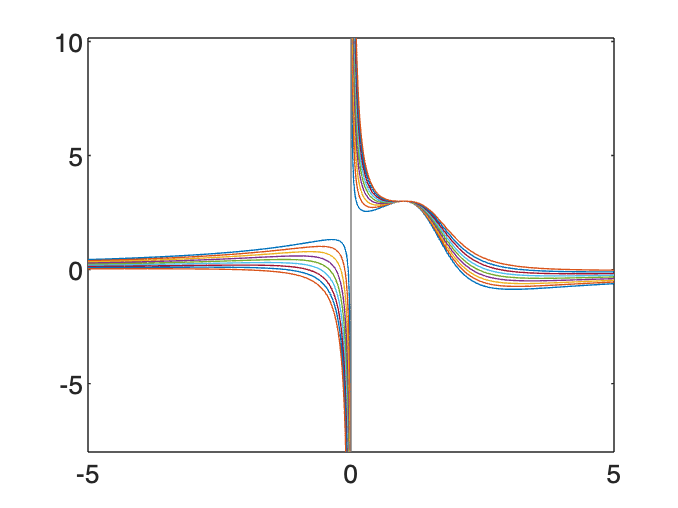

%legend()
hold off

Nota: No me dio el tiempo de graficar la función 3 y de crear una tabla para comparar los tiempos, pero es más rápido y evidente en el Excel. 

### Pregunta #2

Calculos de G y t para la función 3 También se despliega la gráfica.

%fun = @(t) 3*(t.^2+alhpa*(1-t.^2))./(t.*(3-t.^2))
alpha = 0.1

alpha = 0.1000

G1 = @(t) 3*(t.^2+alpha*(1-t.^2))./(t.*(3-t.^2));
fplot(G1)
hold on
[tOpt, fObj] = newtonRaphsonMinimo(G1, 0.3)

tOpt = 0.3117

fObj = 0.6215

alpha = 0.2

alpha = 0.2000

G1 = @(t) 3*(t.^2+alpha*(1-t.^2))./(t.*(3-t.^2));
fplot(G1)
[tOpt, fObj] = newtonRaphsonMinimo(G1, 0.3)

tOpt = 0.4363

fObj = 0.8621

alpha = 0.3

alpha = 0.3000

G1 = @(t) 3*(t.^2+alpha*(1-t.^2))./(t.*(3-t.^2));
fplot(G1)
[tOpt, fObj] = newtonRaphsonMinimo(G1, 0.3)

tOpt = 0.5306

fObj = 1.0338

alpha = 0.4

alpha = 0.4000

G1 = @(t) 3*(t.^2+alpha*(1-t.^2))./(t.*(3-t.^2));
fplot(G1)
[tOpt, fObj] = newtonRaphsonMinimo(G1, 0.3)

tOpt = 0.6101

fObj = 1.1664

alpha = 0.5

alpha = 0.5000

G1 = @(t) 3*(t.^2+alpha*(1-t.^2))./(t.*(3-t.^2));
fplot(G1)
[tOpt, fObj] = newtonRaphsonMinimo(G1, 0.3)

tOpt = 0.6813

fObj = 1.2712

alpha = 0.6

alpha = 0.6000

G1 = @(t) 3*(t.^2+alpha*(1-t.^2))./(t.*(3-t.^2));
fplot(G1)
[tOpt, fObj] = newtonRaphsonMinimo(G1, 0.3)

tOpt = 0.7473

fObj = 1.3538

alpha = 0.7

alpha = 0.7000

G1 = @(t) 3*(t.^2+alpha*(1-t.^2))./(t.*(3-t.^2));
fplot(G1)
[tOpt, fObj] = newtonRaphsonMinimo(G1, 0.3)

tOpt = 0.8105

fObj = 1.4171

alpha = 0.8

alpha = 0.8000

G1 = @(t) 3*(t.^2+alpha*(1-t.^2))./(t.*(3-t.^2));
fplot(G1)
[tOpt, fObj] = newtonRaphsonMinimo(G1, 0.3)

tOpt = 0.8726

fObj = 1.4625

alpha = 0.9

alpha = 0.9000

G1 = @(t) 3*(t.^2+alpha*(1-t.^2))./(t.*(3-t.^2));
fplot(G1)
%axis([0.01 0.9 -5 10])

[tOpt, fObj] = newtonRaphsonMinimo(G1, 0.3)

tOpt = 0.9352

fObj = 1.4904

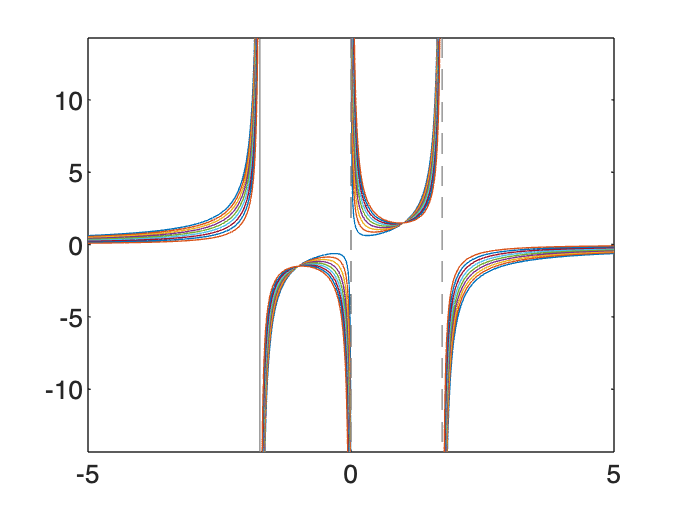

%legend()
hold off

### Problema #4

#### Enfoque tradicional

syms t G
a = 0;
b = 4;

C1 = 1000;
C2 = 10;
%exp con alpha = -0.01

f = @(t) 1/2-t/8;
F = matlabFunction(int(f, 0, t))

F = function_handle with value:
    @(t)t.*(t-8.0).*(-1.0./1.6e+1)


R = @(t) 1- F(t)

R = function_handle with value:
    @(t)1-F(t)


interR = matlabFunction(int(R, 0, t))

interR = function_handle with value:
    @(t)(t.*(t.*-1.2e+1+t.^2+4.8e+1))./4.8e+1



G1 = @(t) (C1*F(t)+C2*R(t))/interR(t)

G1 = function_handle with value:
    @(t)(C1*F(t)+C2*R(t))/interR(t)


fplot(G1, [0.01, 3])

axis([0.01 1 0 750])
grid on
[tOpt, fObj] = newtonRaphsonMinimo(G1, 0.5)

tOpt =          0.388337559284423


fObj =            548.22399172158


#### Enfoque nuevo encontrando una G manteniendo tiempos óptimos

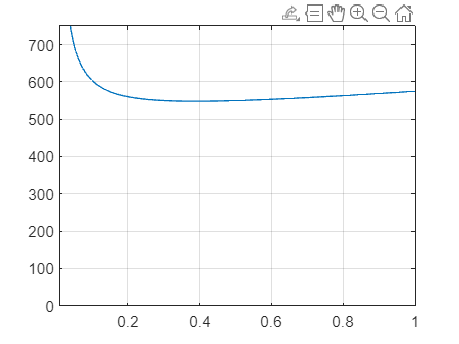

hold off

U =  G*interR(t)-C1*F(t)-C2*R(t)

$$U = \frac{495\,t\,\left(t-8\right)}{8}+\frac{G\,t\,\left(t^{2}-12\,t+48\right)}{48}-10$$

Udf = diff(U,t)

$$Udf = \frac{495\,t}{4}+\frac{G\,\left(t^{2}-12\,t+48\right)}{48}+\frac{G\,t\,\left(2\,t-12\right)}{48}-495$$

Udf = matlabFunction(Udf, 'Vars', {t,G});
Udf = @(G) Udf(tOpt,G);
fplot(Udf, [0,1000]);hold on;fplot(@(t) 0, [0,1000]);title("Plot dfU(t,k)/dt con t=tOpt vs G");xlabel("G");hold off;grid on

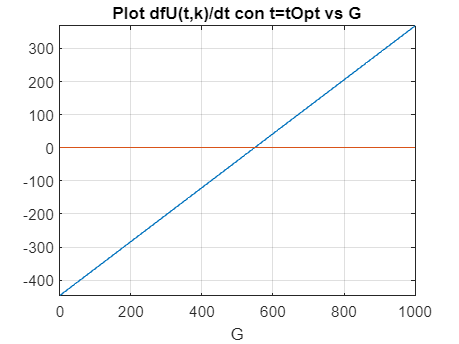

hold off

root = fzero(Udf, 2)

root =           548.223991721581


U = @(t) root*interR(t)-C1*F(t)-C2*R(t)

U = function_handle with value:
    @(t)root*interR(t)-C1*F(t)-C2*R(t)


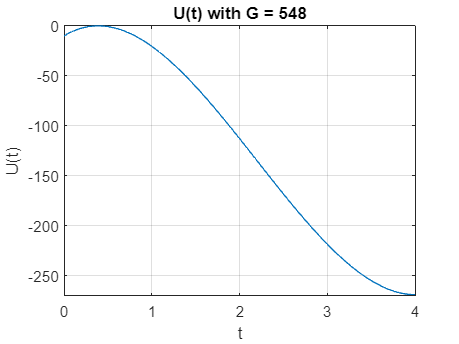

fplot(U, [a,b]);title("U(t) with G = 548");xlabel("t");ylabel("U(t)");grid on

[tOpt2, fObj2] = newtonRaphsonMinimo(U, .5)

tOpt2 =          0.388337559284423


fObj2 =       5.32907051820075e-15


#### Haciendo variaciones en la G

Gc = 990

Gc =    990


U = @(t) Gc*interR(t)-C1*F(t)-C2*R(t)

U = function_handle with value:
    @(t)Gc*interR(t)-C1*F(t)-C2*R(t)


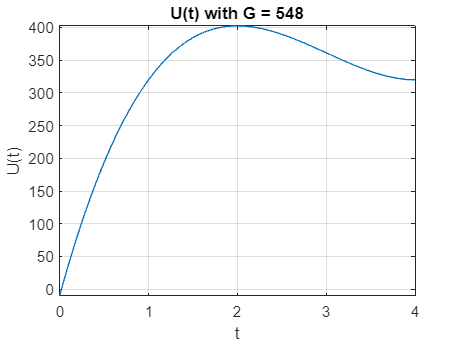

fplot(U, [a,b]);title("U(t) with G = 548");xlabel("t");ylabel("U(t)");grid on

[tOpt2, fObj2] = newtonRaphsonMinimo(U, .5)

tOpt2 =      2


fObj2 =                      402.5


#### Buscamos los valores Esperados de la función.

h = matlabFunction(int(t*U, 0, t))

h = function_handle with value:
    @(t)(t.^2.*(t.*5.28e+3-t.^2.*1.485e+3+t.^3.*1.32e+2-1.6e+2))./3.2e+1


E = int(t*U, 0, tOpt2)

$$E = \frac{1379}{2}$$

EUOpt = h(tOpt2)

EUOpt =                      689.5


## Problema de mochila

a = 1000;
b = 2000;

f = @(t) 1/(b-a);

p = 10;%precio venta
c = 5;%costo compra
s = 2.5;%salvación
cu = p-c; %Utilidad unitaria
co = c-s;%Perdida unitaria

RC = cu/(cu+co); %Factor Crítico

%Qopt = unifinv(RC, a, b)
Qopt = 1500

Qopt = 1500

funSobrantes = @(x) (Qopt-x)*f(x);
unidadesSobrantes = double(integral(funSobrantes, a, Qopt));

funFaltantes = @(x) (x-Qopt)*f(x);
unidadesFaltantes = double(integral(funFaltantes, Qopt, b));

costoProm = co*unidadesSobrantes + cu*unidadesFaltantes;

Utilidad = (p-c)*Qopt - costoProm

Utilidad = 6.5625e+03

a = 1000;
b = 2000;

f = @(t) 1/(b-a);

p = 10;%precio venta
c = 5;%costo compra
s = 2.5;%salvación
cu = p-c; %Utilidad unitaria
co = c-s;%Perdida unitaria

RC = cu/(cu+co); %Factor Crítico

Utilidad =[];
Costo = [];
for i=1000:2000
    %Qopt = unifinv(RC, a, b)
    Qopt = i;
    funSobrantes = @(x) (Qopt-x)*f(x);
    unidadesSobrantes = double(integral(funSobrantes, a, Qopt));
    
    funFaltantes = @(x) (x-Qopt)*f(x);
    unidadesFaltantes = double(integral(funFaltantes, Qopt, b));
    
    costoProm = co*unidadesSobrantes + cu*unidadesFaltantes;
    Costo = [Costo, costoProm];
    Utilidad = [Utilidad, (p-c)*Qopt - costoProm];
end

plot(1000:(1000+length(Utilidad)-1),Utilidad)
hold on
plot(1000:(1000+length(Utilidad)-1),Costo)
hold off
[CostoMinimo, indiceMin] = min(Costo)

CostoMinimo = 833.3338

indiceMin = 668

Qoptima2 = indiceMin+a

Qoptima2 = 1668

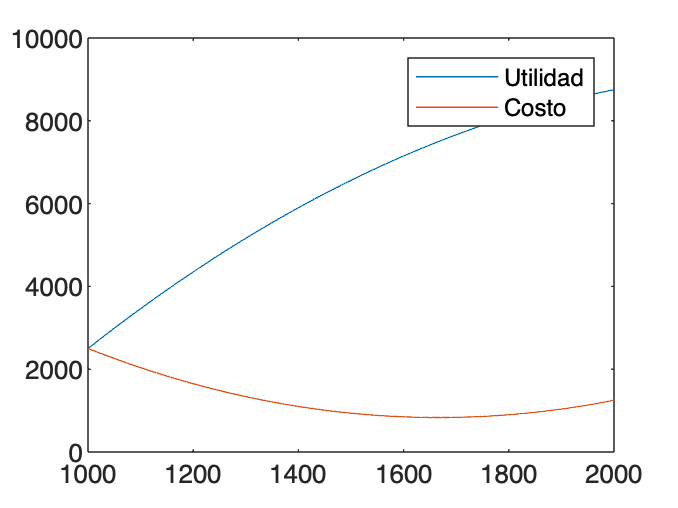

legend("Utilidad", "Costo")

Conclusión: El modelo actual se hace minimizando los costos respecto a una Q, podemos notar que la línea naranja tiene un mínimo. Ahora, si calculamos la utilidad la gráfica no tiene un claro máximo, por ello la función de utilidad como objetivo no es claro. 

### Minimización: Newton-Rhapson

Esta función se manda a llamar para minimizar. Solo es encesario dar la función y un punto cercano que no cruce por asíntotas. 

function [x, fx, i, min] = newtonRaphsonMinimo(f,x)
    %Parámetros iniciales
    max = 52;
    tol = sqrt(eps);
    i = 0;
    cond =  true;
    %Declaramos las funciones anónimas
    f = f;
    fs = sym(f);
    dfs = diff(fs);
    dfs2 = diff(dfs);
    df = matlabFunction(dfs);
    df2 = matlabFunction(dfs2);
    if nargin(df)<1
        error('Function has not second reivate')
    end
    if nargin(df2) < 1
        df2 = @(x) df2();
    end
    while cond
        xp = x;
        x = xp-df(xp)/df2(xp);
        cond = abs((x-xp)/x) > tol && i < max;
        i = i+1;
    end
    min = df2(x) > 0;  
    fx = f(x);
end